1.这一个代码用于分析时间程上的整体编码。

clear;
load('D:\Desktop\Ensemble coding\data\datanum.mat');
all_orientdata = {};
all_num = 4:12;
block = 'EC';
type = 0;
line = 4.5;
co = struct();
meanori = struct();
for i = 1:length(all_num)
    day = sprintf('day%d',all_num(i));
    name = a{1,all_num(i)};
    time = a{2,all_num(i)};
    path = sprintf('D:\\Desktop\\Ensemble coding\\data\\%sdata',time);%数据存储路径
    %这个是用来数据种类的
    num = datanum.(sprintf('data%s',time)).(block);
    [timeseries, stimres, stimIDs] = load_matrix(num, name, path);
    [stimIDs_new] = real_sequence(num, stimres, stimIDs, type);
    [cluster,~] = clusterdata(num, stimIDs_new, timeseries, type, name);
    % 分组为trb
    ori = struct();    
    for ii = num
        tar = find(mod(1:72,4)==0);
        fieldname = sprintf('session%d',ii);
        ori.(fieldname) = floor((stimIDs_new.(fieldname)-1)/18)+1;
        target = cluster.(fieldname).target1;
        blank = cluster.(fieldname).blank;
        random = cluster.(fieldname).random;
        co.(day).(fieldname) = ori.(fieldname);
        co.(day).(fieldname)(73,target) = ori.(fieldname)(4,target);
        co.(day).(fieldname)(73,blank) = 0;
        co.(day).(fieldname)(73,random) = -1;
        
        
        %计算平均朝向
        m = co.(day).(fieldname);
        n = [];
        for trail = 1:66
            for flash = 1:71
                if abs(m(flash+1,trail)-m(flash,trail))<=9
                    n(flash,trail) = (m(flash+1,trail)+m(flash,trail))/2;
                else
                    n(flash,trail) = (m(flash+1,trail)-18+m(flash,trail))/2;
                    if n(flash,trail)<0
                        n(flash,trail) = n(flash,trail)+18;
                    end
                end
            end
        end
        meanori.(day).(fieldname) = n;
    end
end


%提取mua
load('D:\Desktop\Ensemble coding\data\datanum.mat');
all_num = 4:12;
block = 'EC';
type = 0;
pre = 50;%窗口前取50ms
bel = 200; %窗口后取200ms
MUAmean = struct();
for i = 1:length(all_num)
    day = sprintf('day%d',all_num(i));
    name = a{1,all_num(i)};
    time = a{2,all_num(i)};
    path = sprintf('D:\\Desktop\\Ensemble coding\\data\\%sdata',time);%数据存储路径
    
    
    %这个是用来数据种类的
    num = datanum.(sprintf('data%s',time)).(block);
    [MUAs] = load_matrix(num, name, path);
    
    
    for meanorii = 2:36
        oo = meanorii/2;
        meanori_field = sprintf('meanori%d', meanorii);
        
        if ~isfield(MUAmean,meanori_field)
            MUAmean.(meanori_field) = [];
        end

        for ii = num
            fieldname = sprintf('session%d',ii);
            for trail = 1:66
                for flash = 1:71
                    %检查条件是否满足
                    if meanori.(day).(fieldname)(flash,trail) == oo
                        time = (flash*20+100-pre/2):(flash*20+100+bel/2);
                        MUAwindow = MUAs.(fieldname)(trail,1:96,time);
                        
                        %拼接新数据
                        MUAmean.(meanori_field) = cat(1,MUAmean.(meanori_field) ...
                            ,MUAwindow);
                        
                    end
                end
            end
        end
        len = length(MUAmean.(meanori_field)(:,1,1));
        disp(['day',day,';','session','ii',';','length',len])
        %计算均值
        MUAmean.(meanori_field) = mean(MUAmean.(meanori_field),1)
    end
end

dayday5;sessionii;lengthӎ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday5;sessionii;lengthє


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday5;sessionii;length1


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthҭ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѓ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѫ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthД


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthх


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthэ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthҁ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѵ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѸ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthՋ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthҪ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;length՞


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѯ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthԶ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѺ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthՒ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѥ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthՂ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѮ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;length֡


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѷ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthԢ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthҝ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;length՛


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthё


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthԲ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthч


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѤ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthѲ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthЯ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthА


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthя


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthӊ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;lengthЫ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday6;sessionii;length8


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthҁ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthб


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthҎ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthϼ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthѨ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthѮ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthѩ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthъ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthҰ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthԽ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthҪ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthՐ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthї


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthԽ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthѷ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

dayday7;sessionii;lengthՈ


MUAmean = 包含以下字段的 struct :
     meanori2: [1×96×126 double]
     meanori3: [1×96×126 double]
     meanori4: [1×96×126 double]
     meanori5: [1×96×126 double]
     meanori6: [1×96×126 double]
     meanori7: [1×96×126 double]
     meanori8: [1×96×126 double]
     meanori9: [1×96×126 double]
    meanori10: [1×96×126 double]
    meanori11: [1×96×126 double]
    meanori12: [1×96×126 double]
    meanori13: [1×96×126 double]
    meanori14: [1×96×126 double]
    meanori15: [1×96×126 double]
    meanori16: [1×96×126 double]
    meanori17: [1×96×126 double]
    meanori18: [1×96×126 double]
    meanori19: [1×96×126 double]
    meanori20: [1×96×126 double]
    meanori21: [1×96×126 double]
    meanori22: [1×96×126 double]
    meanori23: [1×96×126 double]
    meanori24: [1×96×126 double]
    meanori25: [1×96×126 double]
    meanori26: [1×96×126 double]
    meanori27: [1×96×126 double]
    meanori28: [1×96×126 double]
    meanori29: [1×96×126 double]
    meanori30: [1×96×126 double]
    meanori31: [

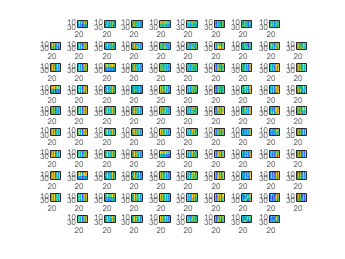

arrayori = [];

for mm = 2:36
    fieldmm  = sprintf('meanori%d',mm);
    arrayori =cat(1,arrayori,MUAmean.(fieldmm));
end
for q = 1:96
    n = find(ChanMap==q);
    subplot(10,10,n);
    imagesc(squeeze(arrayori(:,q,:)));
end

    
figure(2)
n = find(ChanMap==98)
imagesc(squeeze(arrayori(:,q,:)))
